pathdata = '../../../data/sst/'


disp('data is obtained from <a href="https://psl.noaa.gov/data/gridded/data.noaa.oisst.v2.html/">noaa.oisst.v2</a>')
disp('higher resolution is also available <a href="https://psl.noaa.gov/data/gridded/data.noaa.oisst.v2.highres.html/">noaa.oisst.v2 high</a>')

dtype = "sst.wkmean.1990-present"; dmask = 'lsmask'; %! normal
% dtype = ["sst.day.mean.2021","sst.day.mean.2022"]; dmask = 'lsmask.oisst'; %! high resolution, ud is upsidedown.


ufield      = {'Uorg','Sorg','Vorg','fluc','mean'};
ufield{2,1} = [];
[u(1:size(dtype,1))]    = deal(struct(ufield{:}));
time_all    = [];

for id = 1:size(dtype,1)
    if ~isfile([pathdata,char(dtype(id)),'.mat'])
        [lat, lon, time, mask, sst]...
            = F_pre_read_NOAA_SST( [pathdata,char(dtype(id)),'.nc'], [pathdata,dmask,'.nc'] );
        save([pathdata,char(dtype(id)),'.mat'],'sst','time','mask','lat','lon','-v7.3')
    end

    load([pathdata,char(dtype(id)),'.mat'])
    n = size(find(mask),1);
    m = size(time,1);
    [u(id).Uorg, u(id).Sorg, u(id).Vorg, u(id).fluc, u(id).mean, ~] = F_pre_SVD_NOAA_SST(m, time, mask, sst);
    time_all = [time_all;time];
end
loc.mask    = mask;
loc.normal  = mask(:);

imtmp = u.mean;
ir = 3;
sptmp1 = sens(ir).greedyD; sptmp2 = sens(ir).crslcrD; 
[~,p1,p2] = F_fig_SST_sensors_color_compare(imtmp,loc.mask, sptmp1,sptmp2)

p1 =   Line のプロパティ:

              Color: [0 4.4700e-01 7.4100e-01]
          LineStyle: 'none'
          LineWidth: 1.5000e+00
             Marker: 'o'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [36 195 145 312 284 57 13 335 276 274]
              YData: [26 28 52 46 51 19 33 9 93 46]

  すべてのプロパティ を表示


p2 =   Line のプロパティ:

              Color: [8.5000e-01 3.2500e-01 9.8000e-02]
          LineStyle: 'none'
          LineWidth: 1.5000e+00
             Marker: 'x'
         MarkerSize: 8
    MarkerFaceColor: 'none'
              XData: [35 200 276 284 335 38 54 274 273 174]
              YData: [25 27 93 51 9 44 44 47 42 48]

  すべてのプロパティ を表示


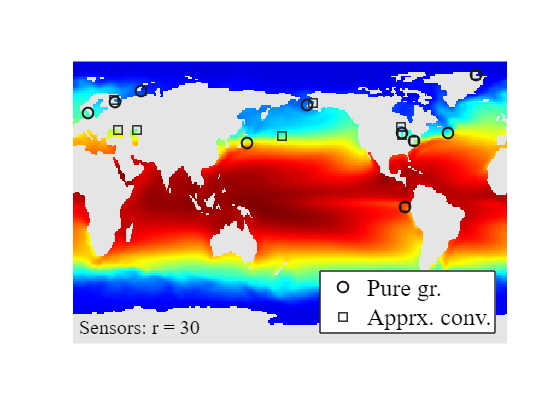

    p1.DisplayName = 'Pure gr.'; p1.MarkerEdgeColor= [0.1,0.1,0.1]; p1.Marker = 'o';
    p2.DisplayName = 'Apprx. conv.'; p2.MarkerEdgeColor = [0.1,0.1,0.1]; p2.Marker = 'square';
text(1,170,[' Sensors',': r = ',num2str(prob.r(ir))],'Fontsize',15,...
        'FontName','Times New Roman','Interpreter','tex');
leg = legend([p1,p2],'Location','southeast');